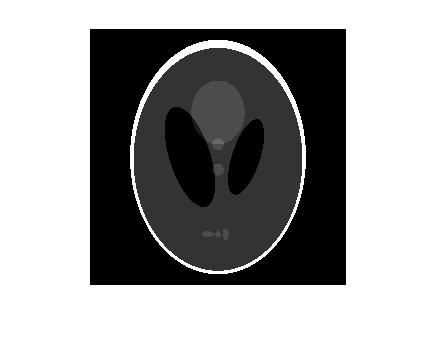

P=phantom(256);
imshow(P)

theta1=0:10:170;
[R1,xp1]=radon(P,theta1);
num_angles_R1=size(R1,2)

num_angles_R1 = 18

theta2=0:5:175;
[R2,xp2]=radon(P,theta2);
num_angles_R2=size(R2,2)

num_angles_R2 = 36

theta3=0:2:178;
[R3,xp3]=radon(P,theta3);
num_angles_R3=size(R3,2)

num_angles_R3 = 90

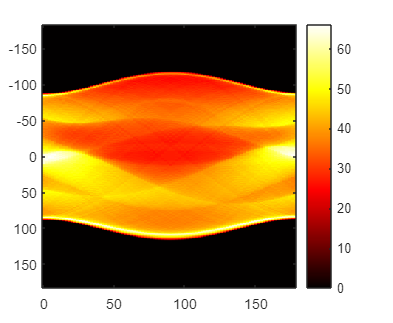

imagesc(theta3,xp3,R3)
colormap("hot")
colorbar

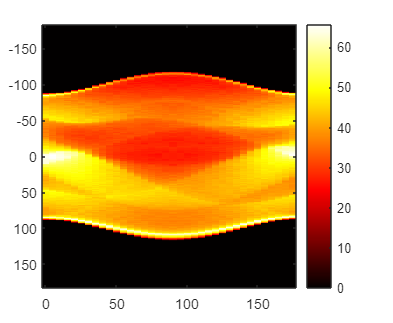

imagesc(theta2,xp2,R2)
colormap("hot")
colorbar

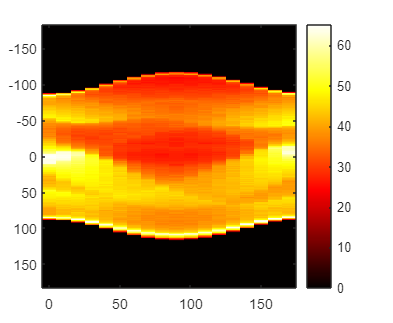

imagesc(theta1,xp1,R1)
colormap("hot")
colorbar

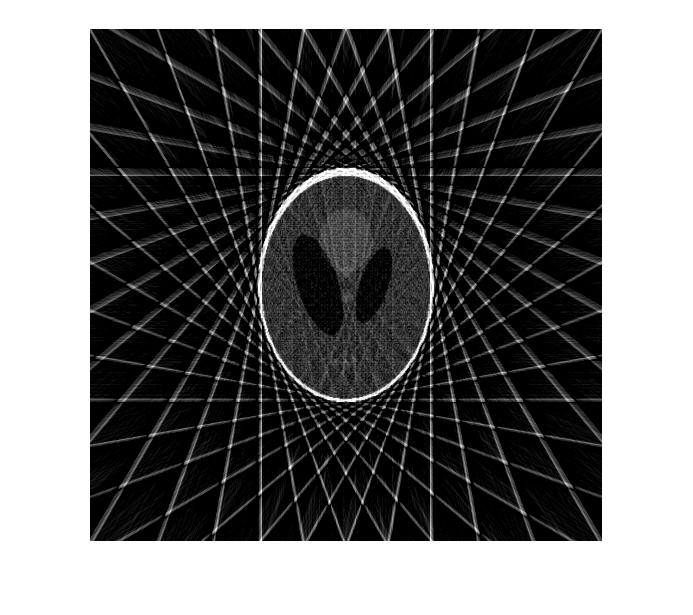

output_size=512;
dtheta1=theta1(2)-theta1(1);
I1=iradon(R1,dtheta1,output_size);
imshow(I1)

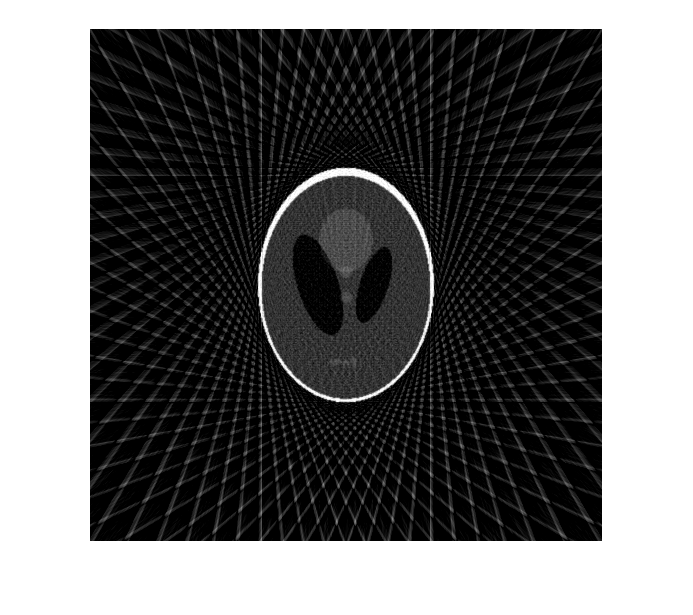

dtheta2=theta2(2)-theta2(1);
I2=iradon(R2,dtheta2,output_size);
imshow(I2)

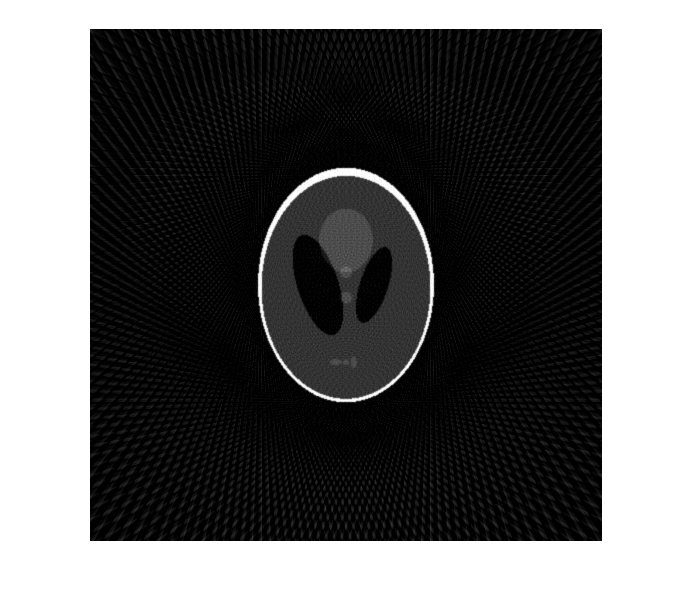

dtheta3=theta3(2)-theta3(1);
I3=iradon(R3,dtheta3,output_size);
imshow(I3)

D=250;
dsensor1=2;
[F1,sensor_pos1,fan_rot_angles1]=fanbeam(P,D,"FanSensorSpacing",dsensor1);
dsensor2=1;
[F2,sensor_pos2,fan_rot_angles2]=fanbeam(P,D,"FanSensorSpacing",dsensor2);
dsensor3=0.25;
[F3,sensor_pos3,fan_rot_angles3]=fanbeam(P,D,"FanSensorSpacing",dsensor3);

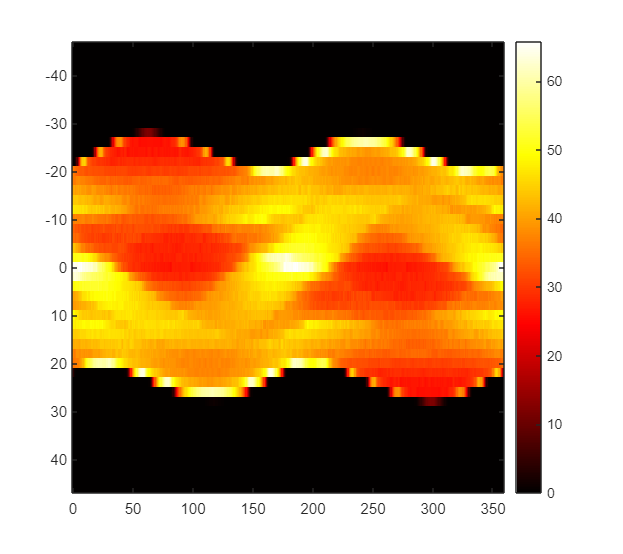

imagesc(fan_rot_angles1,sensor_pos1,F1);
colormap(hot)
colorbar

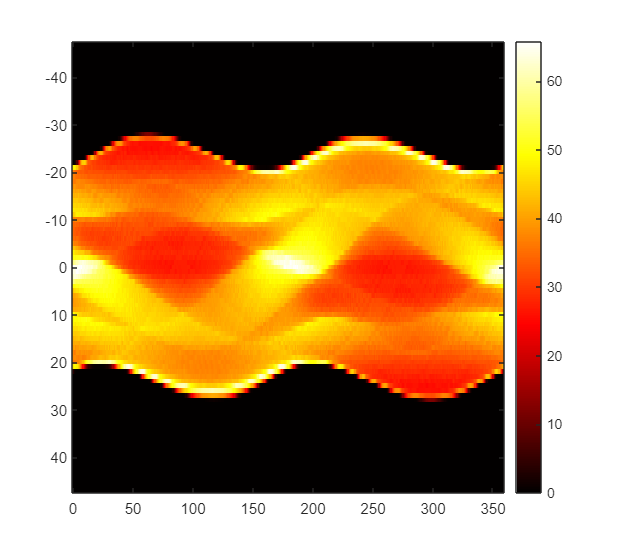

imagesc(fan_rot_angles2,sensor_pos2,F2);
colormap(hot)
colorbar

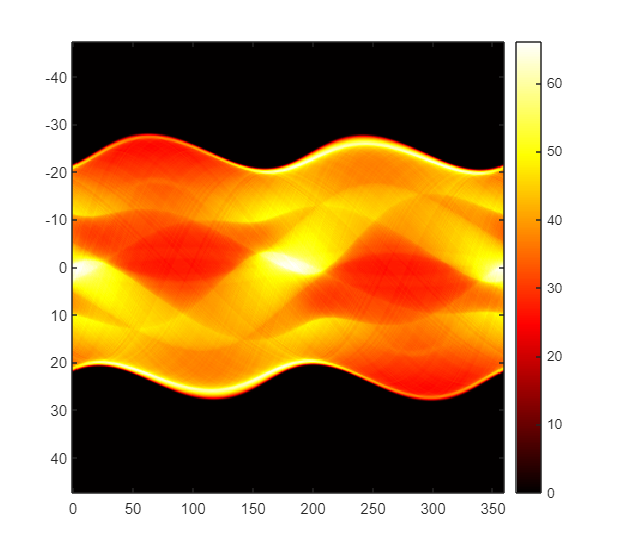

imagesc(fan_rot_angles3,sensor_pos3,F3);
colormap(hot)
colorbar

Ifan1=ifanbeam(F1,D,'FanSensorSpacing',dsensor1,'OutputSize',output_size);
Ifan2=ifanbeam(F2,D,'FanSensorSpacing',dsensor2,'OutputSize',output_size);
Ifan3=ifanbeam(F3,D,'FanSensorSpacing',dsensor3,'OutputSize',output_size);
imshow(I1)

imshow(I2)

imshow(I3)